seconds = 10;
dt = .05;
timesteps = seconds/dt;
A = [1, 0, dt, 0; 
      0, 1, 0, dt;
      0, 0, (1-dt), 0;
      0, 0, 0, (1-dt)];
B = [0, 0;
     0, 0;
    dt, 0;
    0, dt];

X = zeros([timesteps, size(A, 2)]);
X(1, 1) = 100;
X(1, 2) = 100;

U = zeros([timesteps-1, size(B, 2)]);

Q = eye(size(A, 2)) * 1;
R = eye(size(B, 2));

W = zeros([timesteps-1, size(A, 2)]);

gamma = 100;

M = zeros([timesteps, size(A, 2), size(A, 2)]);
Lambda = zeros([timesteps-1, size(A, 2), size(A, 2)]);

r = rubust(X, U, A, B, Q, R, W, gamma, M, Lambda);

r = r.updateMandL();

max = -999.;

for i = 1:size(r.M, 1)
    Mk = squeeze(r.M(i, :, :));
    for e = 1:size(Mk, 1)
        eg = Mk(e);
        if eg > max
            max = eg;
        end
    end  
  
end

gamma = max^(.5)

gamma = 6.6451

r = r.getU();
r.cost()

ans = 16.4003

r.U

ans =  -108.7186 -108.7186
 -103.0596 -103.5544
  -96.9665  -98.0429
  -91.8888  -92.5476
  -86.6367  -87.3238
  -81.2483  -83.1049
  -77.1883  -79.0083
  -73.0768  -74.6669
  -68.6443  -70.6835
  -64.3996  -66.8207


r.X

ans =   100.0000  100.0000         0         0
   99.7675  100.2804   -5.0693   -5.1281
   99.3554   99.7407  -10.3625   -9.7460
   98.8495   99.2007  -14.6080  -14.3483
   97.8232   98.6210  -18.4865  -18.6556
   96.4622   97.9104  -22.1517  -21.8871
   95.4016   97.0853  -24.8774  -24.8872
   93.9265   95.6872  -27.2289  -27.5329
   92.1801   94.4053  -29.6048  -29.9611
   90.3246   92.7477  -31.6934  -31.8934


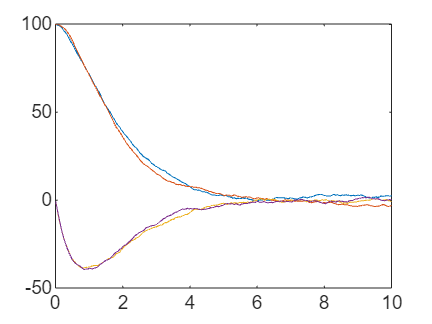

plot(linspace(0, seconds, timesteps), r.X)